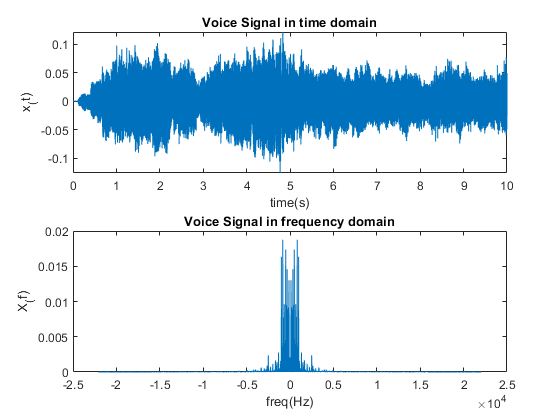

clc;
clear;
close all;
[x_t, fs] = audioread('Audio01.wav');
x_t = x_t';
t_axis = linspace(0, length(x_t) / fs, length(x_t));
X_f = fftshift(fft(x_t))/fs;
f_axis = linspace(-fs / 2, fs / 2, length(X_f));
figure(1)
subplot(211)
plot(t_axis,x_t)
ylabel('x_(t)')
xlabel('time(s)')
title('Voice Signal in time domain')
subplot(212)
plot(f_axis,abs(X_f))
ylabel('X_(f)')
xlabel('freq(Hz)')
title('Voice Signal in frequency domain')

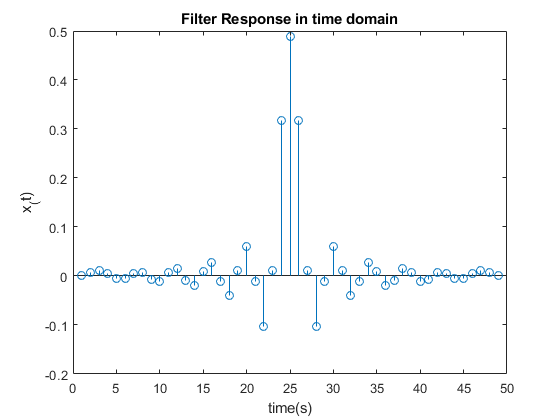


LPF_Coef = load('filter.mat');
LPF_Coef_Num=LPF_Coef.Num;
f_axis2 = linspace(0, 1, 10000);
n=0:length(LPF_Coef_Num)-1;
kernel = exp(-j * n' *pi*f_axis2);
DTFT_FIR_Filter = LPF_Coef_Num * kernel;
LPF_Coef_freq=(fftshift(fft(LPF_Coef.Num)));
figure(2)
stem(LPF_Coef_Num);
ylabel('x_(t)')
xlabel('time(s)')
title('Filter Response in time domain')

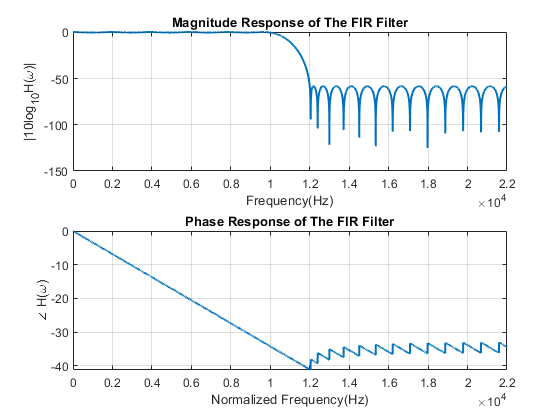


figure('name', 'Frequency Response of The FIR Filter');
subplot(211);
plot(fs*f_axis2/2, 20 * log10(abs(DTFT_FIR_Filter)), 'linewidth', 1.5);
title('Magnitude Response of The FIR Filter');
xlabel('Frequency(Hz)');
ylabel('|10log_{10}H(\omega)|');
xlim([0,2.2e4])
grid on;
subplot(212);
plot(fs*f_axis2/2, unwrap(phase(DTFT_FIR_Filter)), 'linewidth', 1.5);
title('Phase Response of The FIR Filter');
xlabel('Normalized Frequency(Hz)');
ylabel('\angle H(\omega)');
grid on;
xlim([0,2.2e4])

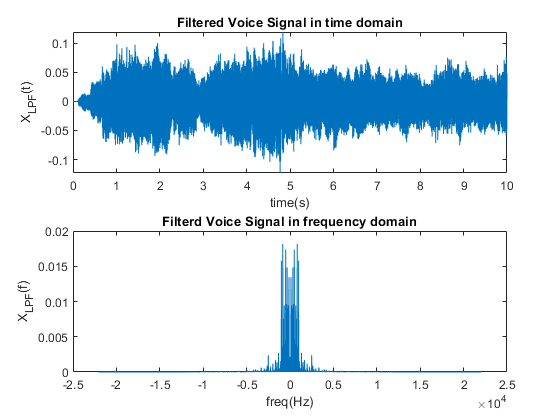

x_lpf=filter(LPF_Coef_Num,1,x_t);
X_lpf_f = fftshift(fft(x_lpf))/fs;
figure(2)
subplot(211)
plot(t_axis,x_lpf)
ylabel('X_{LPF}(t)')
xlabel('time(s)')
title('Filtered Voice Signal in time domain')
subplot(212)
plot(f_axis,abs(X_lpf_f))
ylabel('X_{LPF}(f)')
xlabel('freq(Hz)')
title('Filterd Voice Signal in frequency domain')

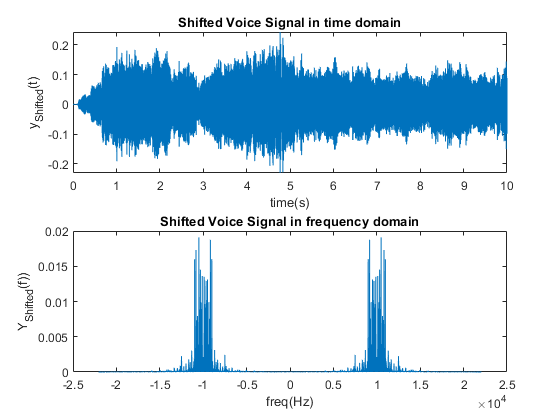


f0=1e4;
s_t=2*cos(2*pi*f0*t_axis);
y_t=x_lpf.*s_t;
Y_f=fftshift(fft(y_t))/fs;

figure(3)
subplot(211)
plot(t_axis,y_t)
ylabel('y_{Shifted}(t)')
xlabel('time(s)')
title('Shifted Voice Signal in time domain')
subplot(212)
plot(f_axis,abs(Y_f))
ylabel('Y_{Shifted}(f))')
xlabel('freq(Hz)')
title('Shifted Voice Signal in frequency domain')

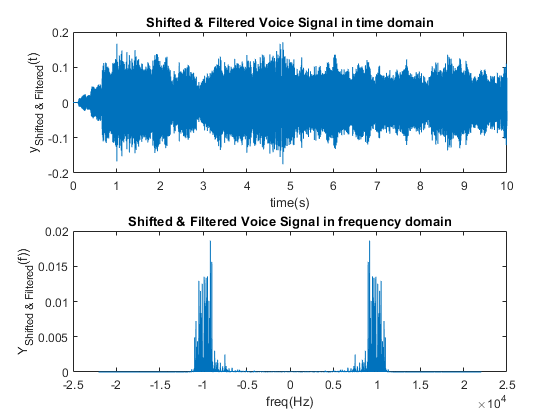



y_filtered=filter(LPF_Coef_Num,1,y_t);
Y_filtered_f=fftshift(fft(y_filtered))/fs;

figure(4)
subplot(211)
plot(t_axis,y_filtered)
ylabel('y_{Shifted & Filtered}(t)')
xlabel('time(s)')
title('Shifted & Filtered Voice Signal in time domain')
subplot(212)
plot(f_axis,abs(Y_filtered_f))
ylabel('Y_{Shifted & Filtered}(f))')
xlabel('freq(Hz)')
title('Shifted & Filtered Voice Signal in frequency domain')


sound(y_filtered,fs)
pause(0.8)


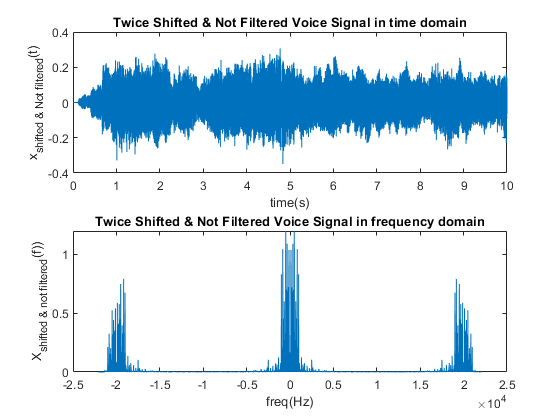

x_pre=y_filtered.*s_t;
x_reconstructed=filter(LPF_Coef_Num,1,x_pre);
X_pre_f=fftshift(fft(x_pre))/fs;
X_reconstructed_f=fftshift(fft(x_reconstructed))/fs;

figure(5)
subplot(211)
plot(t_axis,x_pre)
ylabel('x_{shifted & Not filtered}(t)')
xlabel('time(s)')
title('Twice Shifted & Not Filtered Voice Signal in time domain')
subplot(212)
plot(f_axis,abs(X_pre_f))
ylabel('X_{shifted & not filtered}(f))')
xlabel('freq(Hz)')
title('Twice Shifted & Not Filtered Voice Signal in frequency domain')

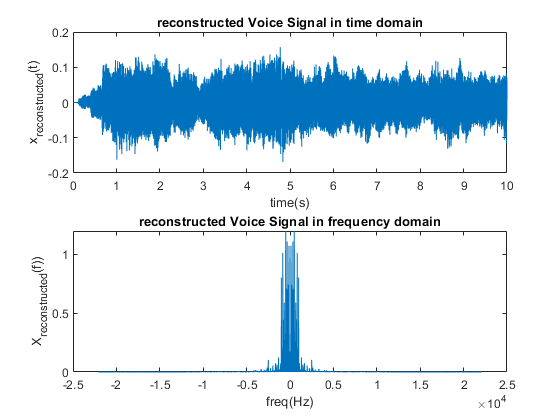


figure(6)
subplot(211)
plot(t_axis,x_reconstructed)
ylabel('x_{reconstructed}(t)')
xlabel('time(s)')
title('reconstructed Voice Signal in time domain')
subplot(212)
plot(f_axis,abs(X_reconstructed_f))
ylabel('X_{reconstructed}(f))')
xlabel('freq(Hz)')
title('reconstructed Voice Signal in frequency domain')


%sound(x_reconstructed,fs) %same as the original sound

MAE=sum(abs(x_reconstructed-x_t))/length(x_t)

MAE = 0.0305

MSE = sum((x_reconstructed - x_t) .^ 2) / length(x_t)

MSE = 0.0015

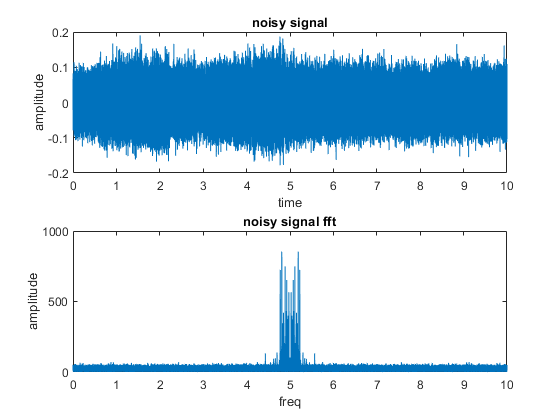

xn=x_t+0.03 * randn(1, length(x_t));
xn_fil=filter(LPF_Coef_Num,1,xn);
y1=xn_fil.*s_t;
y2=filter(LPF_Coef_Num,1,y1);
y3=y2.*s_t;
y_reconstructed=filter(LPF_Coef_Num,1,y3);

figure('name','x_noisy')
subplot(211)
plot(t_axis,xn);
title('noisy signal')
xlabel('time')
ylabel('amplitude')
subplot(212)
plot(t_axis,abs(fftshift(fft(xn))));
title('noisy signal fft')
xlabel('freq')
ylabel('amplitude')

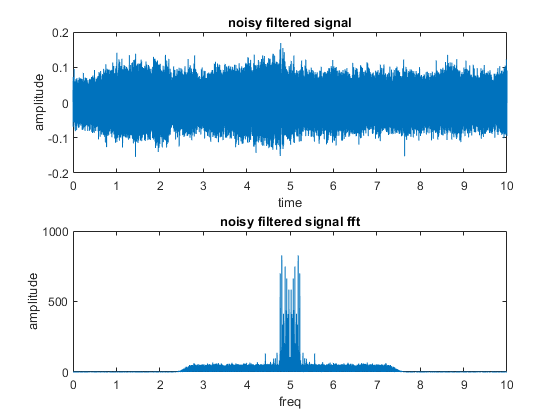


figure('name','x_noisy_filtered')
subplot(211)
plot(t_axis,xn_fil);
title('noisy filtered signal')
xlabel('time')
ylabel('amplitude')
subplot(212)
plot(t_axis,abs(fftshift(fft(xn_fil))));
title('noisy filtered signal fft')
xlabel('freq')
ylabel('amplitude')

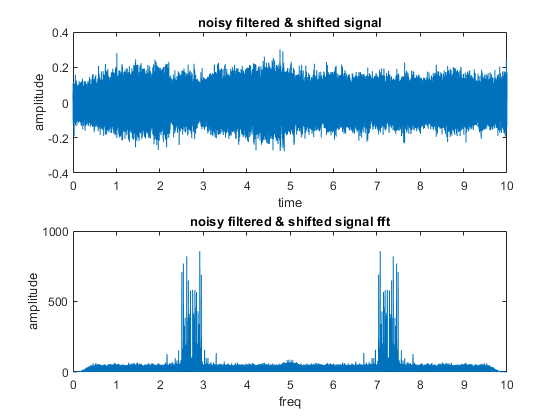


figure('name','x_noisy_filtered & shifted')
subplot(211)
plot(t_axis,y1);
title('noisy filtered & shifted signal')
xlabel('time')
ylabel('amplitude')
subplot(212)
plot(t_axis,abs(fftshift(fft(y1))));
title('noisy filtered & shifted signal fft')
xlabel('freq')
ylabel('amplitude')

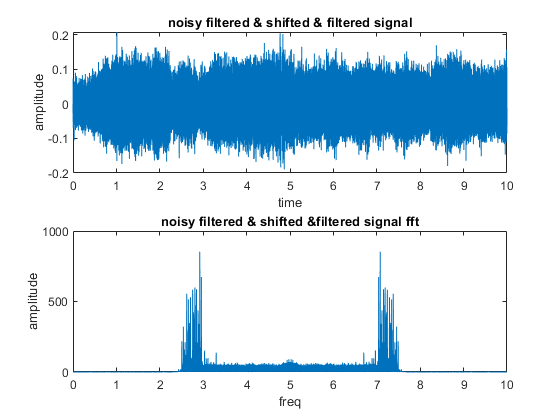


figure('name','x_noisy_filtered & shifted & filtered')
subplot(211)
plot(t_axis,y2);
title('noisy filtered & shifted & filtered signal')
xlabel('time')
ylabel('amplitude')
subplot(212)
plot(t_axis,abs(fftshift(fft(y2))));
title('noisy filtered & shifted &filtered signal fft')
xlabel('freq')
ylabel('amplitude')

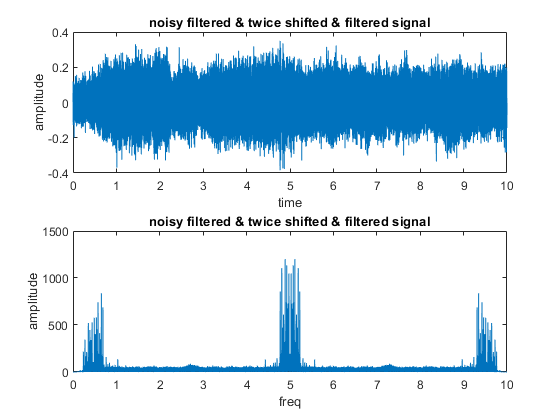


figure('name','x_noisy_filtered & twice shifted & filtered ')
subplot(211)
plot(t_axis,y3);
title('noisy filtered & twice shifted & filtered signal')
xlabel('time')
ylabel('amplitude')
subplot(212)
plot(t_axis,abs(fftshift(fft(y3))));
title('noisy filtered & twice shifted & filtered signal')
xlabel('freq')
ylabel('amplitude')

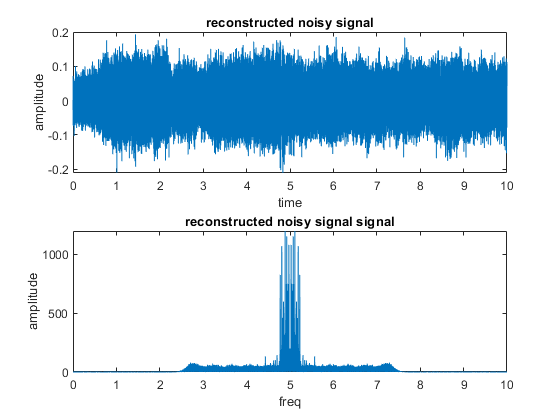


figure('name','reconstructed noisy signal ')
subplot(211)
plot(t_axis,y_reconstructed);
title('reconstructed noisy signal')
xlabel('time')
ylabel('amplitude')
subplot(212)
plot(t_axis,abs(fftshift(fft(y_reconstructed))));
title('reconstructed noisy signal signal')
xlabel('freq')
ylabel('amplitude')